# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Task 1: Explore and Organize Image Dataset 

###  Setup and Configuration

% You must change the 'root' directory path below to match the exact 
% location of the 'metal_plate' dataset on your local computer before running.

root = "C:\Users\egocr\Documents\GitHub\ImageDefectTeam9\metal_plate";

### How we generated the CSV (Commented out)

This section shows the original logic used to scan the folders, label the data as PASS/FAIL, and generate the 'labels.csv' file. You do NOT need to run this again since the CSV is already saved in the repository, but it is kept here for documentation.

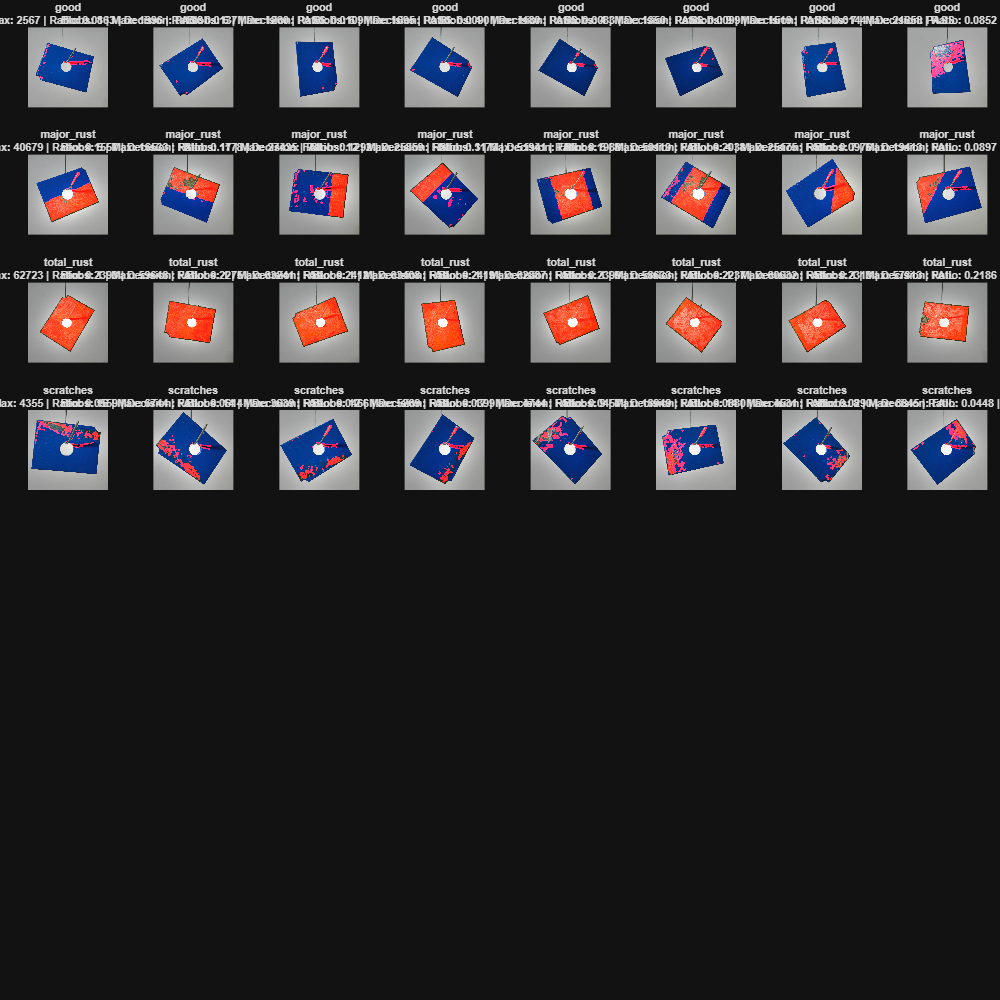




%{
metal_plate Folder Tree
metal_plate
├───ground_truth
│   ├───major_rust
│   ├───scratches
│   └───total_rust
├───test
│   ├───good
│   ├───major_rust
│   ├───scratches
│   └───total_rust
└───train
    └───good
%}
%{
% Define the specific folders and labels

folders = {
    fullfile(root,"train","good"),        "good"
    fullfile(root,"test","good"),         "good"
    fullfile(root,"test","major_rust"),   "major_rust"
    fullfile(root,"test","scratches"),    "scratches"
    fullfile(root,"test","total_rust"),   "total_rust"
    };

% Initialize empty string

filepath = strings(0,1);
defectType = strings(0,1);

% Loop through each folder to find images and assign labels

for i = 1:size(folders,1)
    files = dir(fullfile(folders{i,1}, "*.png"));
    for j = 1:numel(files)
        filepath(end+1,1) = fullfile(files(j).folder, files(j).name);
        defectType(end+1,1) = folders{i,2};
    end
end

% Create pass and fail array

passOrFail = repmat("FAIL", size(defectType));
passOrFail(defectType == "good") = "PASS";

% Combine the three arrays into the labels.csv 

datatable = table(filepath, defectType, passOrFail);
writetable(datatable, fullfile(root, "labels.csv"));

%}

### Datastore 

This section reads the pre-generated CSV and builds the imageDatastore.

% Load the CSV into a table

datatable = readtable(fullfile(root,"labels.csv"), ...
    'Delimiter', ',', ...
    'TextType', 'string', ...
    'VariableNamingRule', 'preserve');

% Create a Datastore with labels

datastore = imageDatastore(datatable.filepath);
datastore.Labels = categorical(datatable.defectType);

## Task 2: Build a Single-Image Inspection Function

defectCategories  = ["good", "major_rust", "total_rust", "scratches"];

% Create a grid
figure('Name', 'Pipeline Overlay Results', 'Position', [100, 100, 1000, 1000]);
tiledlayout(8, 8, 'TileSpacing', 'compact', 'Padding', 'none');

for c = 1:length(defectCategories)
    
    currentLabel = defectCategories(c);
    
    idx = find(datatable.defectType == currentLabel, 8);
    
    for i = 1:length(idx)
        
        nexttile; 
        
        I = imread(datatable.filepath(idx(i)));
        
        [rgb, gray] = standardizeImage(I, [512 512]);
        partMask = segmentPart(rgb);         
        [rgbCorrected, grayCorrected] = correctLighting(rgb, gray);

        [evidenceMask, rustMask, scratchMask] = defectEvidence(rgbCorrected, grayCorrected, partMask);
        
        metrics = extractMetrics(evidenceMask);
        baselineDecision = decideRules(metrics);

        overlay = rgbCorrected;
        redChannel = overlay(:,:,1);
        redChannel(evidenceMask) = 255; 
        overlay(:,:,1) = redChannel;
        
        imshow(overlay);
        
        titleString = sprintf('%s\nBlobs: %d | Max: %d | Ratio: %.4f | Decision: %s', ...
            currentLabel, metrics.numComponents, metrics.maxArea, metrics.areaRatio, baselineDecision); 

        title(titleString, 'Interpreter', 'none', 'FontSize', 8);

    end
end

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function

### Dataset Preparation

70% Training, 15% Validation, 15% Testing

[trainImds, remainderImds] = splitEachLabel(datastore, 0.7, 'randomized');
[valImds, testImds] = splitEachLabel(remainderImds, 0.5, 'randomized');

### Image Augmentation 

inputSize = [224 224 3];

% Random rotations and reflections
augmenter = imageDataAugmenter( ...
    'RandRotation', [-5 5], ...
    'RandXReflection', true);

augTrain = augmentedImageDatastore(inputSize(1:2), trainImds, ...
    'ColorPreprocessing','gray2rgb', 'DataAugmentation', augmenter);

augVal   = augmentedImageDatastore(inputSize(1:2), valImds,   'ColorPreprocessing','gray2rgb');
augTest  = augmentedImageDatastore(inputSize(1:2), testImds,  'ColorPreprocessing','gray2rgb');

### Transfer Learning Setup

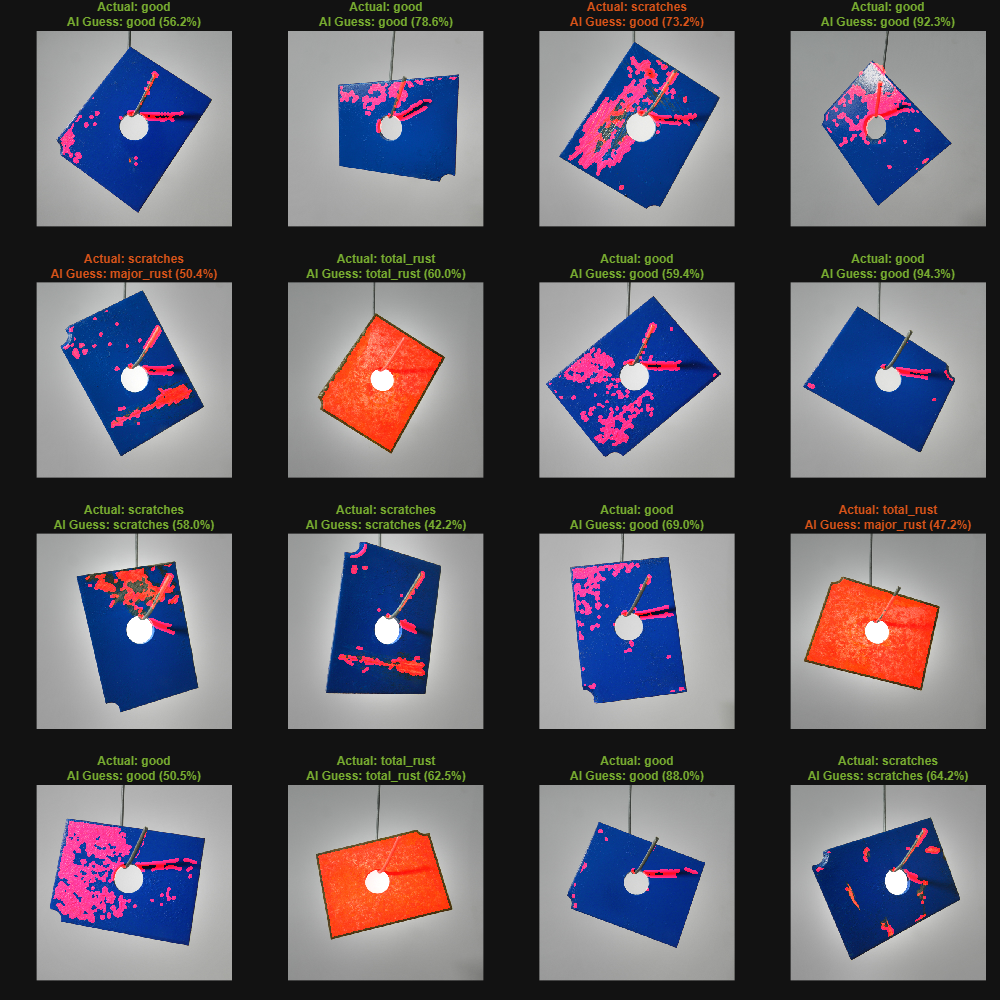

% Load the pre-trained model
net = resnet18;
lgraph = layerGraph(net);

numClasses = numel(defectCategories);  

% Create two new layers
newFC = fullyConnectedLayer(numClasses, 'Name','new_fc', ...
    'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);
newClassLayer = classificationLayer('Name','new_classoutput');


% Replace old layers
lgraph = replaceLayer(lgraph, 'fc1000', newFC);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_predictions', newClassLayer);

### Network Training

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 5, ...
    'MiniBatchSize', 16, ...
    'ValidationData', augVal, ...
    'ValidationFrequency', 5, ...
    'OutputNetwork','best-validation-loss', ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Uncomment if you want to train the network again

%trainedNet = trainNetwork(augTrain, lgraph, options);
%save('trainedNet.mat', 'trainedNet');


load('trainedNet.mat', 'trainedNet');



function [aiLabel, aiScores] = classify(net, roiForNet)
    scores = predict(net, roiForNet);
    classNames = net.Layers(end).Classes;
    [aiScores, idx] = max(scores);
    aiLabel = classNames(idx); 
end

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result

function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision] = inspectPart(I, net)

    % Task 2
    [rgb, gray] = standardizeImage(I, [512 512]);
    partMask = segmentPart(rgb);
    [rgbCorrected, grayCorrected] = correctLighting(rgb, gray);
    [evidenceMask, ~, ~] = defectEvidence(rgbCorrected, grayCorrected, partMask);
    evidenceMetrics = extractMetrics(evidenceMask);
    baselineDecision = decideRules(evidenceMetrics);

    % Task 3
    roiForNet = imresize(rgbCorrected, [224 224]);
    [finalLabel, confidenceScore] = classify(net, roiForNet);

    % Overlay image
    evidenceOverlay = rgbCorrected;
    redChannel = evidenceOverlay(:,:,1);
    redChannel(evidenceMask) = 255;
    evidenceOverlay(:,:,1) = redChannel;

end



### Quick Test

figure('Name', 'AI Batch Testing', 'Position', [100, 100, 1000, 1000]);
tiledlayout(4, 4, 'TileSpacing', 'compact', 'Padding', 'none');

testImages = shuffle(testImds); 
testImages = subset(testImages, 1:16);

for i = 1:16
    nexttile;
    
    I = readimage(testImages, i);
    actualRealLabel = testImages.Labels(i);
    
    [finalLabel, confidenceScore, evidenceOverlay, ~, ~] = inspectPart(I, trainedNet);
    
    imshow(evidenceOverlay);
    
    titleStr = sprintf('Actual: %s\nAI Guess: %s (%.1f%%)', ...
        actualRealLabel, finalLabel, confidenceScore * 100);
    
    % Color the text
    if actualRealLabel == finalLabel
        title(titleStr, 'Interpreter', 'none', 'FontSize', 9, 'Color', '#77AC30'); % Green
    else
        title(titleStr, 'Interpreter', 'none', 'FontSize', 9, 'Color', '#D95319'); % Red
    end
end

## Task 4: Evaluate Inspection System Performance

Now that you've built a hybrid inspection system that integrates classical evidence with an AI decision, your goal in this step is to test the system on a batch of images.

The results of this test should be summarized with a confusion matrix, report yield, and defect rates across the entire batch of images.

Write a script (e.g. `runInspectionSuite.m`) that:

- Splits data into train/test (e.g., `splitEachLabel(...)` or a fixed split)

- Evaluates the trained AI model and trains the inspection system on a test set and logs outcomes

- Produces a confusion matrix with `confusionmat(...)` / `confusionchart(...)`

- Summarizes yield and defect counts in tables and plots

- Visualizes common failure cases (e.g. by creating a montage of common errors using `montage(...)`)

% Here, it is recommended to create a separate runInspectionSuite.m file
% (or include as a local helper function) that combines the work you've done 
% so far here and additionally performs the steps outlined in the task description. 
% You can run it from here.





## Task 5: Test and Evaluate System Robustness

Your goal in this step is to assess how your system performs under simulated variations. You can simulate image inspection station variation by altering the lighting, blur, or noise in the images. Here are some suggested distortions to apply:

- Brightness/contrast: `imadjust(...)`

- Blur: `imgaussfilt(...)`

- Noise: `imnoise(...)`

Then, re-run the evaluation. In other words, run `runInspectionSuite.m `again with the same image set after applying distortions to the images.

Compare how performance changes across conditions by reporting how accuracy and false-reject rates change under simulated variations.

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?